**Question 1**

clf

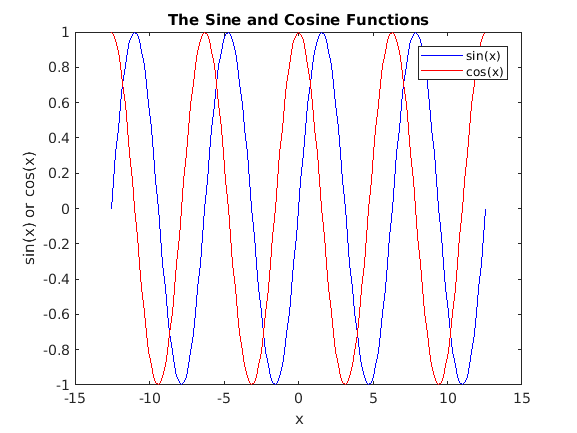


% Plotting sin(x), cos(x)
x = -4*pi : pi/20 : 4*pi;

figure(1)
plot(x, sin(x), 'b-', x, cos(x), 'r-')
xlabel('x')
ylabel('sin(x) or cos(x)')
title('The Sine and Cosine Functions')
legend('sin(x)', 'cos(x)')


%hold on
%plot([-5 -5], [-1 1])

**Question 2**

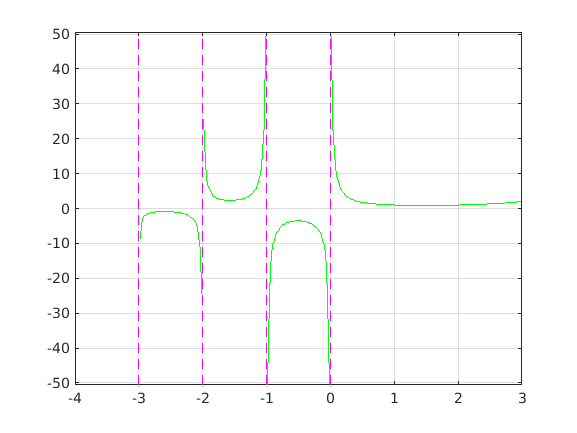

% evaluating gamma, but avoiding the asymptotes
% that are at x = -3, -2, -1, 0
% plot magenta dashed lines at asymptotes

xs = -3: 0.02 :3;
ys = gamma(xs);

plotGammaWithAsymptotes(xs, ys)

**Question 3**

Plotting y = 2x^2 + 8x-1 on [-5,5] and draw y = 0, x = 0 and plot the intercepts of the graph along with the vertex as circles. Then label the x and y axes and place a legend on the graph. 

a = 2; b = 8; c = -1; 
p = [a, b, c];

xs = -5 : 0.01 : 5; 
y = @(x) a*x .^ 2 + b*x + c;
ys = y(xs);

% Range
xMin = min(xs); xMax = max(xs); 
yMin = min(ys); yMax = max(ys);

% Vertex
vx = -b/(2*a);
vy = c - b^2/(4*a);

% Intercepts
xIntercepts = roots(p)

xIntercepts =    -4.1213
    0.1213


yIntercept = y(0)

yIntercept = -1

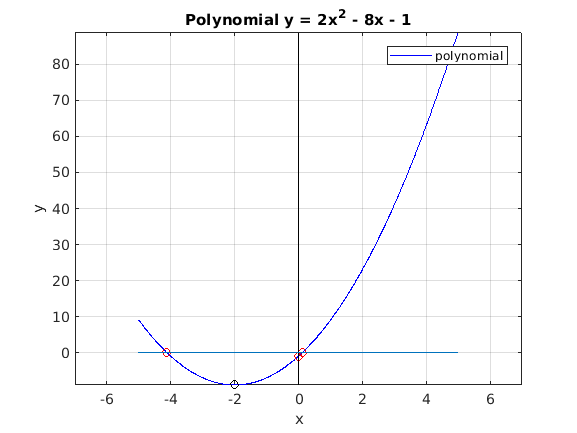

clf
% Plotting main graph
plot(xs, ys, 'b-')
axis([xMin-2, xMax+2, yMin, yMax])
grid on
hold on 

% Plotting the vertex
plot(vx, vy, 'ko')

% And plotting x,y intercepts (at most only 2
% x intercepts occur)
plot(xIntercepts(1), 0, 'ro')
plot(xIntercepts(2), 0, 'ro')
plot(0, yIntercept, 'ro')

% Plotting the x and y-axes
plot([0 0], [yMin yMax], 'k-') % y-axis
plot([xMin xMax], [0 0]) % x-axis

xlabel('x')
ylabel('y')
title('Polynomial y = 2x^2 - 8x - 1')
legend('polynomial')


% TODO - fix getintercepts file, got away
% this time using roots in matlab optimization
% package!

**Question 4: **

volumeTetrahedron(2)

ans = 0.9428

showVolume

The volume of a tetrahedron with equilaterial triangle side lengths of 23.00000 is: 1433.89470
